# Exercise 4: Prune the network to compress structurally

This exercise introduces a new technique: *network projection*. This technique analyzes the covariance of neural excitations on layers of interest and reduces the number of learnable parameters by modifying layers to operate in a projective space. Although the operations of the layer take place in a typically lower rank projective space, the expressivity of the layer remains high as the width—i.e., the number of neural activations—remains unchanged when compared to the original network architecture. This can be used in place of or in addition to pruning and quantization.

net = savedStruct.trainedNet;
%% prune the trained network with data
% assumble the network to 
arrds = arrayDatastore(dataTable, "OutputType","same");
mbqTrain = minibatchqueue(arrds, OutputAsDlarray=1, MiniBatchFormat="SSBC"); 
npca = neuronPCA(net,mbqTrain,VerbosityLevel="steps");

Using solver mode "direct".
Computing covariance matrices for activations connected to: "conv_1/in"
Computing eigenvalues and eigenvectors for activations connected to: "conv_1/in"
Computing covariance matrices for activations connected to: "conv_1/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv_1/out"
Computing covariance matrices for activations connected to: "conv_2/in"
Computing eigenvalues and eigenvectors for activations connected to: "conv_2/in"
Computing covariance matrices for activations connected to: "conv_2/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv_2/out"
Computing covariance matrices for activations connected to: "conv_3/in"
Computing eigenvalues and eigenvectors for activations connected to: "conv_3/in"
Computing covariance matrices for activations connected to: "conv_3/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv_3/out"
Computing covariance matrices for activations co

netProjected = compressNetworkUsingProjection(net,npca, "LearnablesReductionGoal",0.2); 

Compressed network has 20.3% fewer learnable parameters.
Projection compressed 10 layers: "conv_1","conv_2","conv_3","conv_4","conv_5","conv_6","conv_7","conv_8","conv_9","fc"


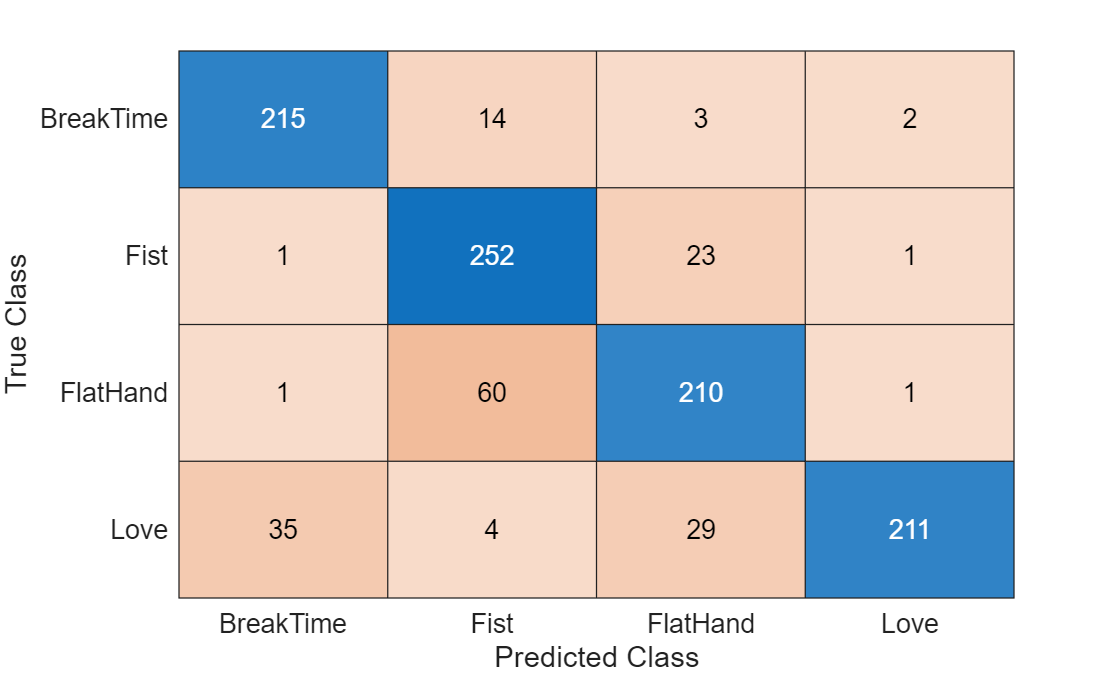

%% test the pruned network
scoresPruned = minibatchpredict(netProjected,xTest);
YPruned = onehotdecode(scoresPruned,classNames,2);
confusionchart(label_Test,YPruned);

accuracyPruned = mean(YPruned == label_Test) 

accuracyPruned = 0.8757